%% mesh

## 起手式

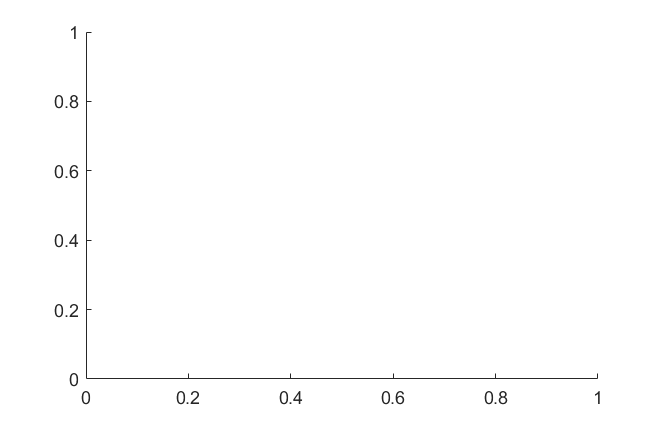


clc,clear,close all
figure("Units","centimeters","Position",[20,10,14,9])
ax = gca;
ax.FontSize = 10.5;

## 生成x y z 数据


t = 0:0.1:2*pi;
x = t;
y = sin(t);
z = exp(t);

[xq,yq] = meshgrid(x,y);%% 生成格点
zq = griddata(x,y,z,xq,yq);%%由x, y, z数据得到格点上的数据

## 格点图

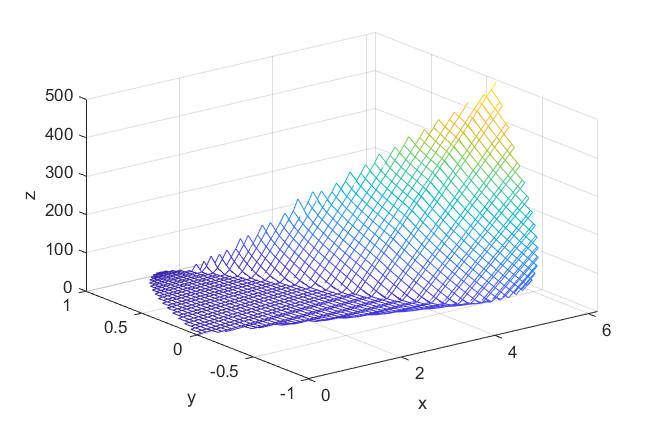


mesh(ax,xq,yq,zq)
xlabel(ax,'x',"FontSize",10.5);
ylabel(ax,'y',"FontSize",10.5);
zlabel(ax,'z',"FontSize",10.5);

## 曲面图

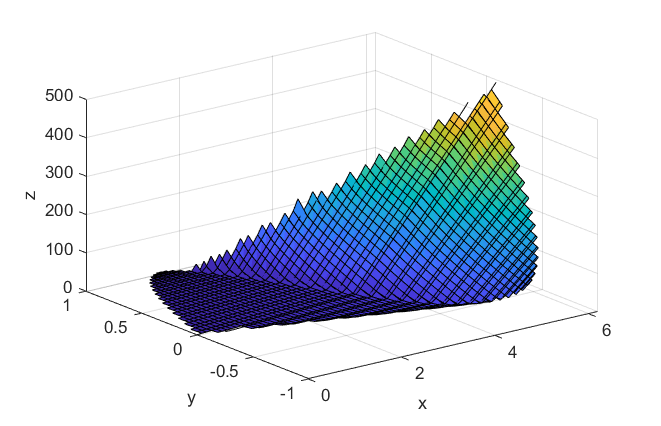


figure("Units","centimeters","Position",[20,10,14,9])
ax = gca;
ax.FontSize = 10.5;
surf(ax,xq,yq,zq)
xlabel(ax,'x',"FontSize",10.5);
ylabel(ax,'y',"FontSize",10.5);
zlabel(ax,'z',"FontSize",10.5);